## Example_live.mlx

This live script runs several functions, resulting in an estimation of muscle fascicle length and pennation angle. An example ultrasound image  (example_ultrasound_image.mat) and default parameters (parms.mat) are loaded. Parameters can be adjusted in this live script and their effect visualized in real-time. The script consists of the following parts:

- Step 0: Load and plot image

- Step 1: Frangi filtering

- Step 2a: Aponeurosis detection

- Step 2b: Fascicle detection

- Step 3: Fascicle length calculation

The following functions are called:

- FrangiFilter2D (and subfunctions)

- cut_apo

- deepapo_func

- superapo_func

- dohough

Tim van der Zee 2020-08-29, tim.vanderzee@ucalgary.ca

% Create path
clear all; close all; clc
fold = fileparts(which('example_live.mlx'))

fold = 'C:\Users\Tim\Documents\GitHub\ultrasound-automated-algorithm'

cd(fold); % set cd to that folder
addpath(genpath(cd)); % add all subfolders of cd to path


## Step 0: Load and plot image

Here, the image and parameters are loaded and the size of the image is calculated. The image is from the vastus lateralis muscle in a healthy adult. The image should be nxmxp, with n the amount of rows in the image, m the amount of columns and p the intensity in each of the RGB colours. Generally, m>n (landscape) and p = 3. In addition, a pixel to cm ratio is defined. For this particular image, a 4 cm scale is shown on the right edge. Pixel to cm ratio can be obtained by counting the amount of pixels along the scale, and dividing by 4. The positive horizontal axis points to the right and in proximal direction, the positive vertical axis points upward. All angles are defined relative to the positive horizontal axis (positive angles denote anti-clockwise). Generally, for these types of images, muscle fascicle angles  should be positive. Aponeuroses angles can be negative because the vastus lateralis lies more superficially on the distal end than on the proximal end due to its origin on the femur. 

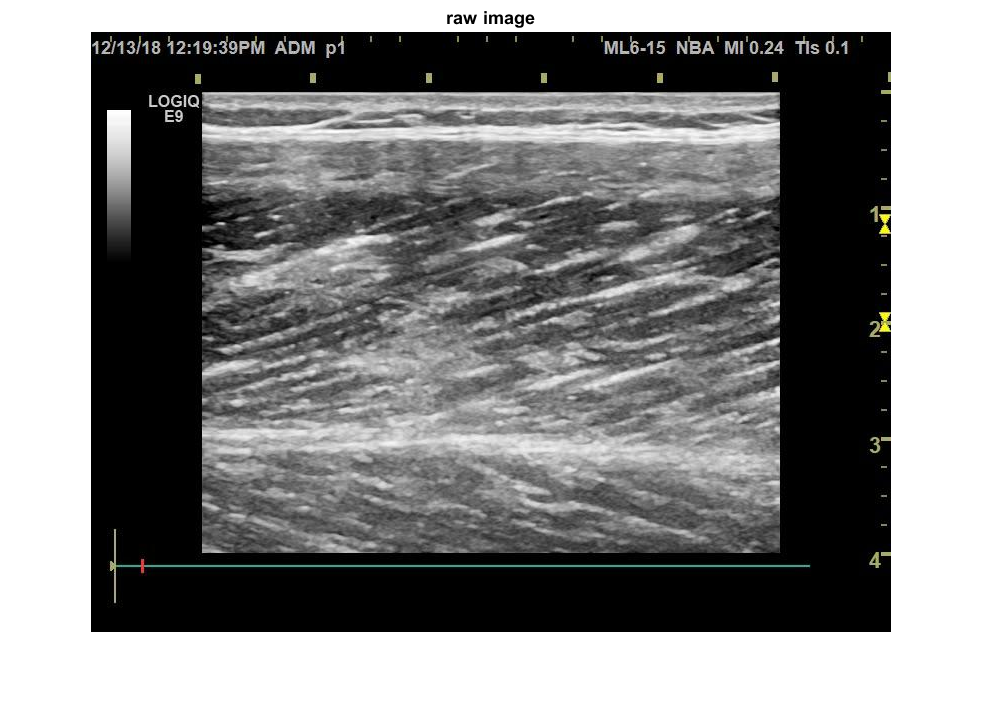

load('parms.mat'); % start with default parameters
load('example_ultrasound_image.mat'); % example image
[n,m,p] = size(data); % nxmx3

figure;
imshow(data); title('raw image')


ncm = 4; % cm
npix = 461; % pixels
pixtocm = npix/ncm; % pixel to centimeter ratio (scale on image)


## Step 1: Frangi filtering

As described in the documentation of FrangiFilter2D, the function uses the eigenvectors of the Hessian to compute the likeliness of an image region to vessels, according to the method described by Frangi, 2001 (Chapter 2). The function was written by Marc Schrijver on 2/11/2001 and re-Written by D.Kroon in May 2009, from University of Twente. The function seems to have been intended to identify vessels, but works well for muscle fascicles as well since they also are line-like / vessel-like. The image is filtered using a gaussian filter with different sizes (i.e. sigma values), within the range specified by FrangiScaleRange. Thinner lines can be detected by using small values for the range, and thicker lines can be detected by using large values for the range. Aponeuroses are thicker than muscle fascicles and therefore the range used for aponeurosis should be larger than the range used for fascicles. For fascicles, the smallest or second smallest range possible is recommended (1-2 or 1-3). 

% aponeurosis filtering
parms.apo.frangi.BlackWhite = false; % DO NOT check this box unless you want to detect black objects instead of white ones
parms.apo.frangi.FrangiScaleRange(1) = 8; % lower limit on thickness range (pixels)
parms.apo.frangi.FrangiScaleRange(2) = 14; % upper limit on thickness range (pixels)
aponeurosis = FrangiFilter2D(double(rgb2gray(data)), parms.apo.frangi);

Current Frangi Filter Sigma: 8
Current Frangi Filter Sigma: 10
Current Frangi Filter Sigma: 12
Current Frangi Filter Sigma: 14


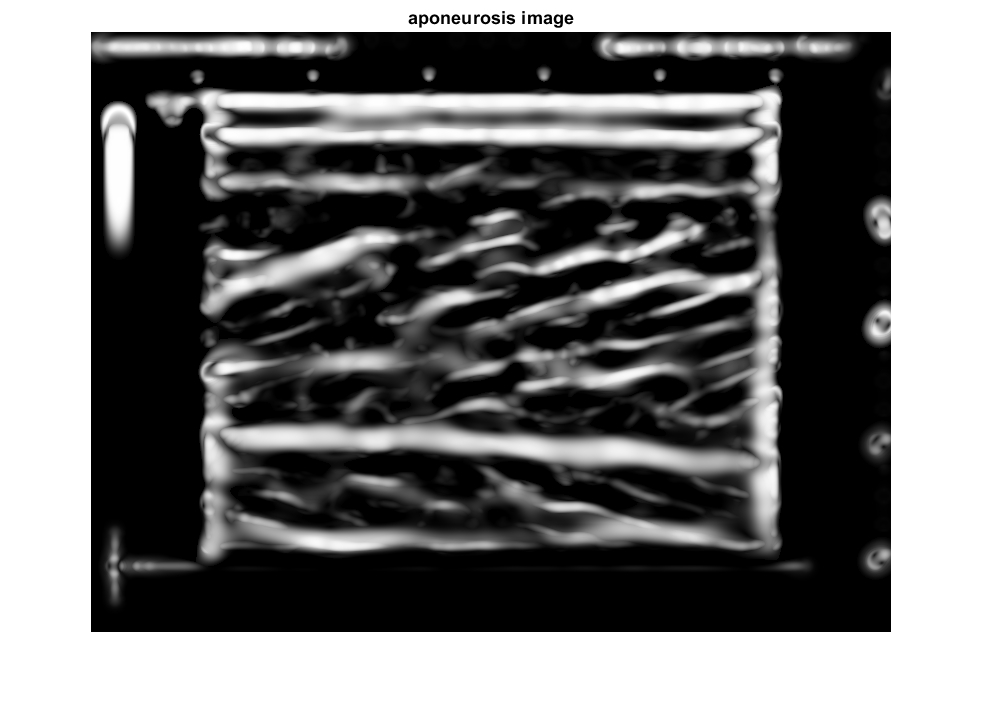

figure; imshow(aponeurosis); title('aponeurosis image')


% fascicle filtering
parms.fas.frangi.BlackWhite = false; % DO NOT check this box unless you want to detect black objects instead of white ones
parms.fas.frangi.FrangiScaleRange(1) = 1; % lower limit on thickness range (pixels)
parms.fas.frangi.FrangiScaleRange(2) = 3; % upper limit on thickness range (pixels)
parms.fas.frangi.FrangiScaleRatio = 1 % step size within specified range (default = 2)

parms = struct with fields:
    frangi: [1×1 struct]
       fas: [1×1 struct]
       apo: [1×1 struct]


fascicle = FrangiFilter2D(double(rgb2gray(data)), parms.fas.frangi);

Current Frangi Filter Sigma: 1
Current Frangi Filter Sigma: 2
Current Frangi Filter Sigma: 3


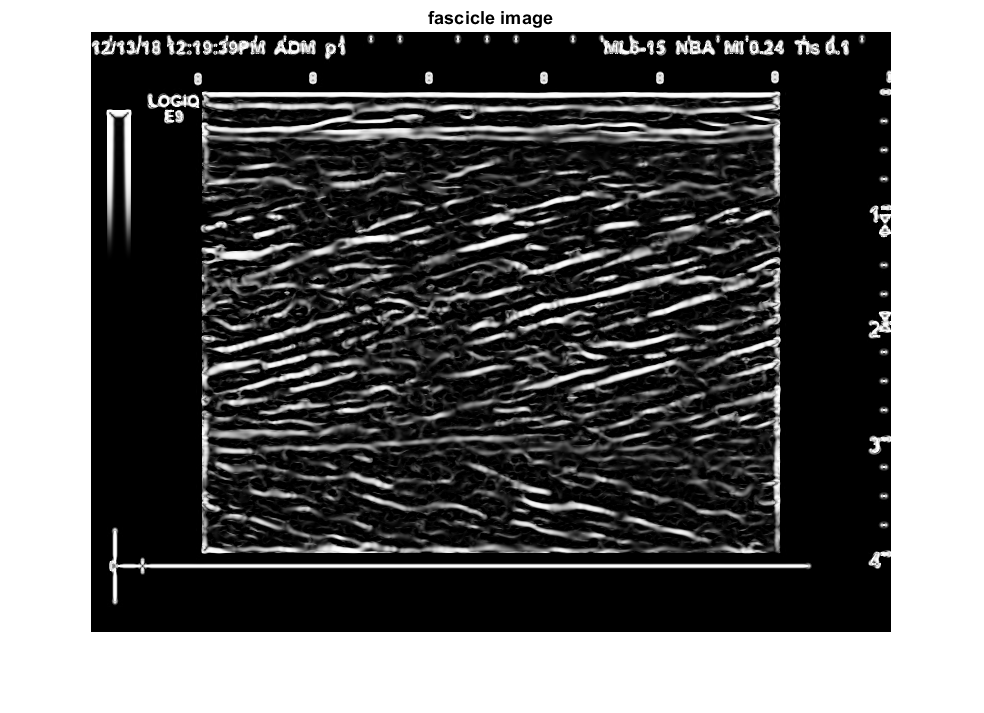

figure; imshow(fascicle); title('fascicle image')

## Step 2a: Aponeurosis detection

Aponeuroses are detected by scanning the image for the object that is most likely to be the aponeurosis. This is done seperately for deep and superficial aponeurosis, because they generally look slightly different. The superficial aponeurosis is generally easier to detect because is closed to the skin (usually within 1 cm) and therefore close to the ultrasound probe. Due to deformation in the muscle (i.e changes in muscle thickness), the deep aponeurosis can shift up and down, change angle and change intensity. It is advised to select minimal criteria for the deep aponeurosis and give up when those are not met. This implies that the ultrasound image has to have a certain quality, and that the quality of the deep aponeurosis is most critical. The upper X% of the image is used for superficial aponeurosis and the lower X% for the deep aponeurosis, with X specified by the parameter parms.apo.cut. Only objects within a certain angle range, length and length ratio are considered. Length ratio refers to the ratio between lengths of the longest and second longest object. If length ratio is close to 1, selection is based on location rather than length. For how exactly criteria are used to select aponeuroses, see: [https://www.biorxiv.org/content/10.1101/2020.08.23.263574v1](https://www.biorxiv.org/content/10.1101/2020.08.23.263574v1)

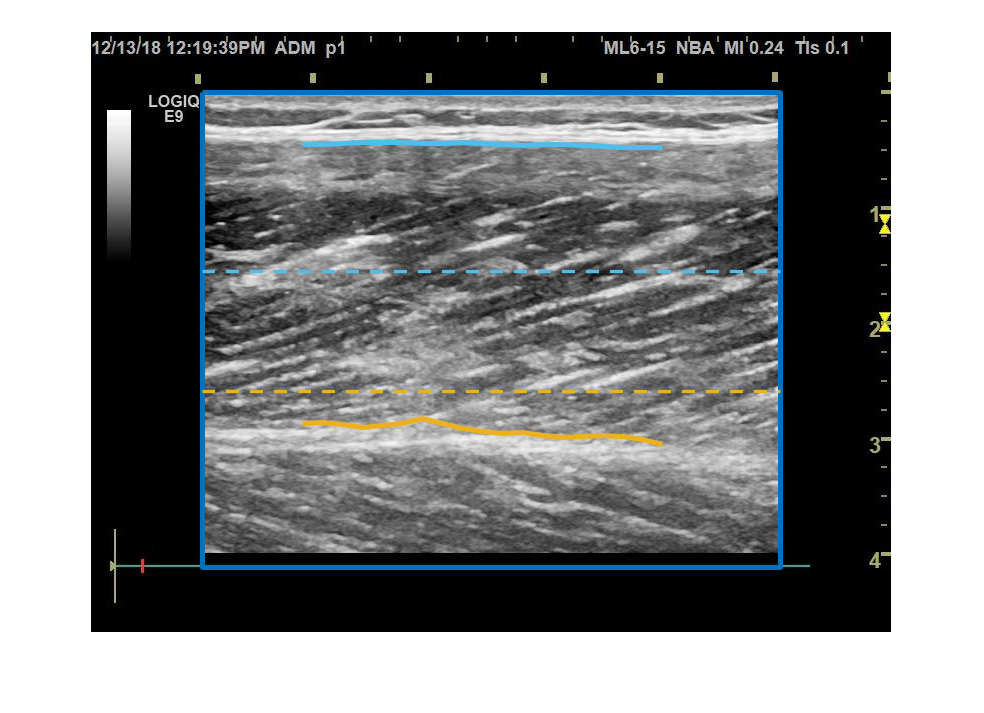

% Cutting
parms.apo.cut = 0.4; % fraction of vertical ascribed to each aponeurosis
[aponeurosis_cutted, vert, hori] = cut_apo(data, aponeurosis); % Cutting the muscle pixels out of the total image

% Define the horizontal aponeurosis spacing
parms.apo.margin = 100; % distance between start aponeurosis objects and the sides (pixels)
parms.apo.spacing = 20; % horizontal spacing for aponeurosis (pixels) 
parms.apo.apox = (vert(1)+parms.apo.margin):parms.apo.spacing:(vert(2)-parms.apo.margin);
n_apo = length(parms.apo.apox);
c = parms.apo.cut;

% Plot regions (dashed thin lines)
figure; color = get(gca,'colororder'); imshow(data); hold on; 
plot([vert(1) vert(2) vert(2) vert(1) vert(1)],[hori(1) hori(1) hori(2) hori(2) hori(1)], 'linewidth',3,'color',color(1,:)); % image region
plot([vert(1) vert(2)], [n*(1-c) n*(1-c)], '--','linewidth', 2,'color', color(3,:))
plot([vert(1) vert(2)], [n*c n*c], '--','linewidth', 2, 'color', color(6,:))

% Selection criteria
parms.apo.superrange(1) = -30; % smallest superficial aponeurosis angle considered (deg)
parms.apo.superrange(2) = 10; % largest superficial aponeurosis considered (deg)
parms.apo.deeprange(1) = -20; % smallest superficial aponeurosis angle considered (deg)
parms.apo.deeprange(2) = 10; % largest superficial aponeurosis considered (deg)
parms.apo.minlength = 200; % minimal length for aponeurosis object (pixels) 
parms.apo.maxlengthratio = 0.8; % maximal ratio between longest and second longest object
parms.apo.fillgap = 5; % gap filling in the deep aponeurosis (pixels)

% Find aponeurosis
deep_aponeurosis = deepapo_func(aponeurosis_cutted, parms.apo);
super_aponeurosis = superapo_func(aponeurosis_cutted, parms.apo);

% Plot objects (thick solid lines)
plot(parms.apo.apox, deep_aponeurosis, 'linewidth',3, 'color', color(3,:))
plot(parms.apo.apox, super_aponeurosis, 'linewidth',3, 'color', color(6,:)); 


% Determine superficial aponeurosis angle
thickness = (mean(deep_aponeurosis-super_aponeurosis,'omitnan')) / pixtocm;
dx = parms.apo.apox(end) - parms.apo.apox(round(n_apo/2));
dy = super_aponeurosis(:,round(n_apo/2)) - super_aponeurosis(:,end); % negative if downward
betha = atan2d(dy,dx);  

if sum(isnan(deep_aponeurosis)) == length(deep_aponeurosis)
    disp('Not able to find a deep aponeurosis, try changing the parameters')
end

if sum(isnan(super_aponeurosis)) == length(super_aponeurosis)
    disp('Not able to find a superficial aponeurosis, try changing the parameters')
end

% Show superficial aponeurosis angle and muscle thickness
disp(['Superficial aponeurosis angle = ' , num2str(round(betha,3)), ' deg' ])

Superficial aponeurosis angle = -1.273 deg


disp(['Muscle thickness = ' , num2str(round(thickness,3)), ' cm' ])

Muscle thickness = 2.482 cm


## Step 2b: Fascicle detection

As with the aponeurosis detection, a region is selected for fascicle detection. Fascicles are assumed to lie in the middle of the image, where horizontal middle is the horizontal middle of the image and vertical middle is the middle between aponeuroses (parms.fas.middle). A fraction of the image below and above the vertical middle is kept (parms.fas.cut(1)) and a fraction of the sides is cut (parms.fas.cut(2)). The Hough transform is done for angles within the range specified by parms.fas.range. The angle is adjusted for the superficial aponeurosis angle, so that the angle range in fact relates to pennation angle instead of fascicle angle. A weighted average is taken over the top N most frequently occuring fascicle angles (alpha), where N is specified by parms.fas.npeaks. For visualization purposes only, the most frequently occuring line is stored in fascicle_lines and plotted. Note that the angle of this line only equals alpha if parms.fas.npeaks = 1.

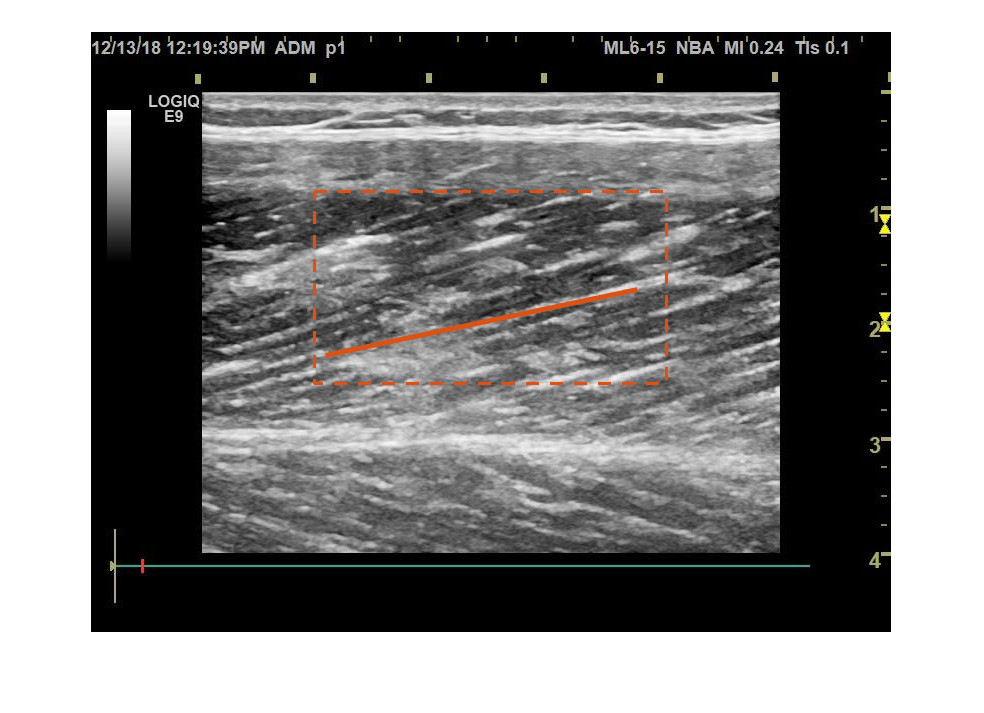

% Cutting
parms.fas.middle = round((mean(deep_aponeurosis) + mean(super_aponeurosis))/2);
parms.fas.cut(1) = 0.16; % relative amount kept from the middle
parms.fas.cut(2) = 0.28; % relative amount cut on the sides
c = parms.fas.cut;

% Plot regions (dashed thin lines)
figure; imshow(data); hold on
plot([m*c(2) m*(1-c(2)) m*(1-c(2)) m*c(2) m*c(2)], ...
    [parms.fas.middle-(n*c(1)), parms.fas.middle-(n*c(1)) parms.fas.middle+(n*c(1)) parms.fas.middle+(n*c(1)) parms.fas.middle-(n*c(1))] ...
    ,'--', 'linewidth', 2, 'color', color(2,:))

% Parameters
parms.fas.range(1) = 10; % smallest pennation angle considered (deg)
parms.fas.range(2) = 30; % largest pennation angle considered (deg)
parms.fas.npeaks = 10; % amount of Hough angles included in weighted average
parms.fas.range = parms.fas.range + round(betha); % take superficial aponeurosis angle into account
    
% Do Hough transform
[alpha, fascicle_lines] = dohough(fascicle,parms.fas);

% Plot the most frequently occuring line (thick solid line)
plot([fascicle_lines(1,1) fascicle_lines(1,3)],[fascicle_lines(1,2) fascicle_lines(1,4)],'LineWidth',3, 'color', color(2,:))


% Display fascicle angle
disp(['Fascicle angle = ' , num2str(round(alpha,3)), ' deg' ])

Fascicle angle = 14.392 deg


## Step 3: Fascicle length and pennation angle calculation

Based on geometry, pennation angle (phi) equals the difference between fascicle angle (alpha) and superficial aponeurosis angle (betha). Fascicle length (faslen) equals the ratio between muscle thickness and pennation angle. See Fig. 1 in *van der Zee & Kuo (2020a):* [https://www.biorxiv.org/content/10.1101/2020.08.23.263574v1](https://www.biorxiv.org/content/10.1101/2020.08.23.263574v1)

% Pennation angle (phi) and fascicle length
phi = alpha - betha;
faslen = thickness ./ sind(phi);

% Display pennation angle and fascicle length
disp(['Pennation angle = ' , num2str(round(phi,2)), ' deg' ])

Pennation angle = 15.66 deg


disp(['Fascicle length = ' , num2str(round(faslen,2)), ' cm'])

Fascicle length = 9.19 cm



% Save parameters for next use
cd(fold)
save('parms.mat','parms')

## Application: energetic cost of cyclic muscle force production

Fascicle lengths and pennation angles may be used to estimate muscle moment arms and the amount of mechanical work done by the muscle. See *van der Zee & Kuo (2020b):* [https://www.biorxiv.org/content/10.1101/2020.08.25.266965v1](https://www.biorxiv.org/content/10.1101/2020.08.25.266965v1)